依赖[统一实验分析作图v19.1.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases/)

声水初始、学会和迁移到光水的热图

Uninhibited=UniExp.DataSet('\\Data-Server-2\个人数据\张天夫\202505\MOp全钙.v2.mat');
Uninhibited.TagSplitTrial(seconds([-3,3]));
%由于行为和水混用CD2通道导致多拆出了一个假回合
Uninhibited.RemoveTrials(Uninhibited.TableQuery("TrialUID",DateTime=datetime('2022-08-06 20:26:00',TimeZone='local'),TrialIndex=31).TrialUID);

%该日期行为记录了99回合，标通道拆出100回合，每个回合的刺激类型对不上
Uninhibited.RemoveDateTimes(datetime('2023-01-13 09:39:00',TimeZone='local'));
TrialDuration=seconds(6);
LLP=Uninhibited.CheckForLightLeakage(seconds([0,0.2]),["LightOnly","LightWater"]);
Uninhibited.LightLeakageInterpolation(LLP.BlockUID(LLP.Probability>0.95),seconds([0,0.2]),["LightOnly","LightWater"]);
Uninhibited.ResampleTrials(milliseconds(125),TrialDuration);

GroupNtats=UniExp.NtatsCellStrip(Uninhibited.QueryNTATS(UniExp.ReadQueryTable("D:\Users\张天夫\Documents\MATLAB\Transfer-learning\查询表.xlsx",'Fig1G'),UniExp.Flags.ZScore,1:24,UniExp.Flags.Median));

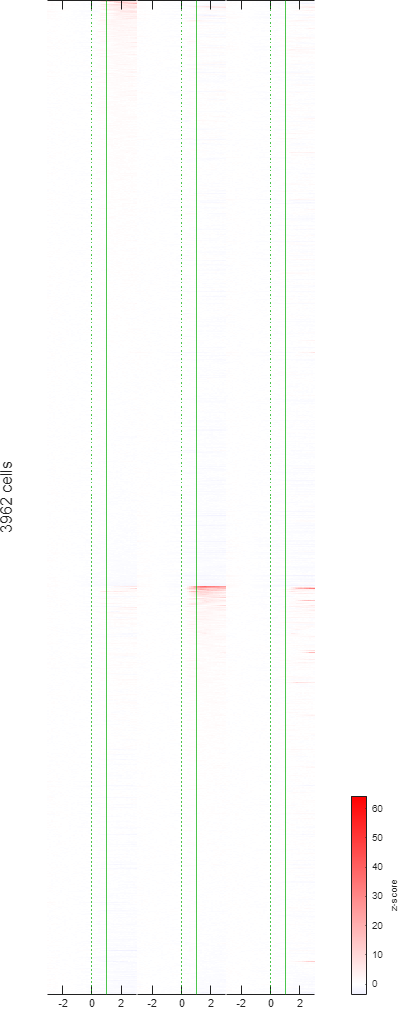

Fig=figure;
[Layout,Axes]=UniExp.LanearHeatmap(UniExp.HeatmapSort(GroupNtats,["Naive","Learned"]).NTATS{:,:,["Naive","Learned","Transfer"]},XData=[-3,3],LMHColor=[0,0,1;1,1,1;1,0,0],Flags=[UniExp.Flags.HideYAxis,UniExp.Flags.SymmetricColormap],Layout=tiledlayout(5,4,TileSpacing='none',Padding='tight'));
CB=colorbar;
CB.Layout.Tile=20;
CB.Label.String='z-score';
for A=1:3
	xline(Axes(A),0,':',Color=[0,0.681,0]);
	xline(Axes(A),1,'-',Color=[0,0.681,0]);
	Axes(A).TickDir='in';
	Axes(A).Layout.TileSpan=[5,1];
	box(Axes(A),'on');
end
ylabel(Layout,sprintf('%u cells',height(GroupNtats)));
MATLAB.Graphics.FigureAspectRatio(2,5,MATLAB.Flags.Amplify);
print(Fig,TransferLearning.ProjectPath('Fig1G.svg'),'-dsvg');